# Project 8 (Water flow)

12.36 in book

%{
Rate of water flow
   originally from 'MATLAB for Engineers', sixth edition, by Holly Moore,
   chapter 12, problem 12.36
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -To model the rate of water flowing into a tank
Input:
   -flow rate
   -time interval
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   - 
%}

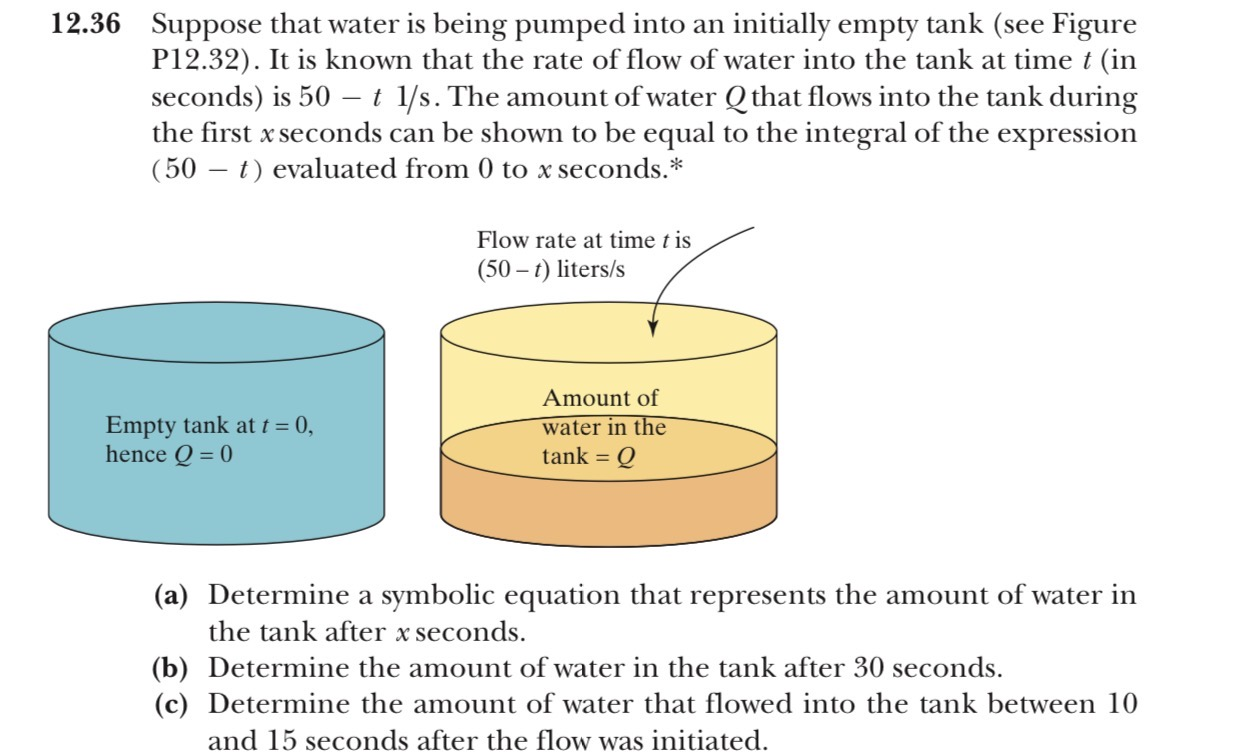

clc
clear
% symbolic equation for amount of water in tank
syms x % makes x a symbolic variable
W = 50 - x; % defines the rate of flow of water into the tank
Q = int(W, x); % defines the amount of water that has flowed into the tank over a time interval

% amount of water in tank after 30 seconds
Wt = int(W, 0, 30); 

% amount of water that flowed into tank between 10 and 15 s
Qflowed = int(W, 10, 15); % takes the integral to find the amount that flowed into the tank between 10 and 15s
fprintf('The amount of water (liters) that flowed into that tank, from 10s to 15s after the flow began, is:');

The amount of water (liters) that flowed into that tank, from 10s to 15s after the flow began, is:

display(Qflowed); % displays the amount of water that flowed in on this interval

$$Qflowed = \frac{375}{2}$$

% Calculate the amount of water in the tank at the user-defined time
start = userEntry(); % calls the user entry function
amountInTank = int(W, 0, start); % finds amount that has flowed in at user entered time
fprintf('The amount of water in the tank at %d seconds is: ', start);

The amount of water in the tank at 2 seconds is: 

display(amountInTank); % displays the amount of water that has entered at this time

$$amountInTank = 98$$

% plot of the rate water is entering the tank
t = 0:1:50; % defines t in seconds on the interval 0 to 50
w = 50 - t % rate of water flow into tank

w =     50    49    48    47    46    45    44    43    42    41    40    39    38    37    36    35    34    33    32    31    30    29    28    27    26    25    24    23    22    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1


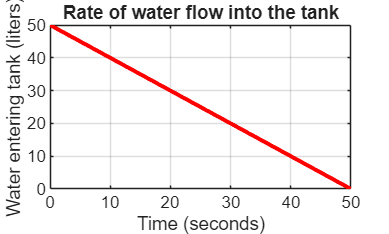

plot(t, w, 'r-', 'LineWidth', 2) % plots the rate water is flowing into the tank
title('Rate of water flow into the tank') % titles the plot
xlabel('Time (seconds)') % labels the x-axis
ylabel('Water entering tank (liters)') % labels the y-axis
grid on % turns on the grid lines

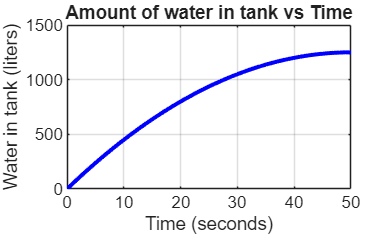

% plot of amount of water in the tank
Wint = 50*t - (1/2)*(t.^2); % the function for how much water is in the tank
plot(t, Wint, 'b-', 'linewidth', 2) % plots how much water has flowed into the tank
title('Amount of water in tank vs Time') % titles the plot
xlabel('Time (seconds)') % labels the x-axis
ylabel('Water in tank (liters)') % labels the y-axis
grid on % turns the grid lines on

% allows users to enter a time to see how much water is in tank
function [start, stop] = userEntry  % creates a function for users to enter values
start = input('Enter a starting time, in seconds, between 0 and 50: ');
if start < 0 && start > 50  
    start = 30;   % if the user enters a value outside the limits, start time will be 30
end
stop = input('Enter an ending time, in seconds, between 0 and 50: ');
if stop < 0 && stop > 50
    stop = 50;  % if the user enters a value outside of the limits, the end time is 50
if stop < start
    disp('error, try again');  % if the user enters a value outside of the limits or greater than the start value, they are given this message
end
    
end 
end